% The sampling rate is 1000 Hz
FS = 1000

FS = 1000


% Load ECG 1 into Nx1 vector from the file ecg_signal_1.dat
ecg1 = load("ecg_signal_1.dat")

ecg1 =    -0.7144
   -0.5507
   -0.4588
   -0.5588
   -0.5728
   -0.7222
   -0.4073
   -0.3029
   -0.3346
   -0.4770



% Load ECG 2 into Nx1 vector from the file ecg_signal_2.dat
ecg2 = load("ecg_signal_2.dat")

ecg2 =    -0.8876
   -0.9138
   -0.8862
   -0.8801
   -0.9306
   -0.9065
   -0.9026
   -0.9175
   -0.9477
   -0.9752



% Select the interval [2 s, 3s] samples from ECG 1
ecg1_interval = ecg1(2*FS:3*FS)

ecg1_interval =     0.2034
    0.2550
    0.1001
   -0.2046
   -0.1735
   -0.0119
    0.0967
   -0.1328
   -0.3282
   -0.4718



% Sample times for the interval 1
ecg1_interval_t = linspace(2, 3, FS + 1)

ecg1_interval_t =     2.0000    2.0010    2.0020    2.0030    2.0040    2.0050    2.0060    2.0070    2.0080    2.0090    2.0100    2.0110    2.0120    2.0130    2.0140    2.0150    2.0160    2.0170    2.0180    2.0190    2.0200    2.0210    2.0220    2.0230    2.0240    2.0250    2.0260    2.0270    2.0280    2.0290    2.0300    2.0310    2.0320    2.0330    2.0340    2.0350    2.0360    2.0370    2.0380    2.0390    2.0400    2.0410    2.0420    2.0430    2.0440    2.0450    2.0460    2.0470    2.0480    2.0490



% Select the interval [1 s, 2s] samples from ECG 2
ecg2_interval = ecg2(1*FS:2*FS)

ecg2_interval =    -1.2695
   -1.2924
   -1.2221
   -1.2411
   -1.2788
   -1.2715
   -1.2791
   -1.2311
   -1.2032
   -1.2451



% Sample times for the interval 2
ecg2_interval_t = linspace(1, 2, FS + 1)

ecg2_interval_t =     1.0000    1.0010    1.0020    1.0030    1.0040    1.0050    1.0060    1.0070    1.0080    1.0090    1.0100    1.0110    1.0120    1.0130    1.0140    1.0150    1.0160    1.0170    1.0180    1.0190    1.0200    1.0210    1.0220    1.0230    1.0240    1.0250    1.0260    1.0270    1.0280    1.0290    1.0300    1.0310    1.0320    1.0330    1.0340    1.0350    1.0360    1.0370    1.0380    1.0390    1.0400    1.0410    1.0420    1.0430    1.0440    1.0450    1.0460    1.0470    1.0480    1.0490


% Compute FFT
fft_ecg1 = fft(ecg1)

fft_ecg1 = 1.0e+03 *

  -3.9228 + 0.0000i
  -0.3537 - 0.3407i
   0.0223 - 0.4443i
  -0.4060 - 0.2338i
   0.2170 - 0.3065i
  -0.2220 - 0.1067i
   0.1418 - 0.0263i
   0.0670 - 0.2253i
   0.0124 - 0.0264i
   0.1467 - 0.0864i


fft_ecg2 = fft(ecg2)

fft_ecg2 = 1.0e+03 *

  -8.5874 + 0.0000i
   0.9408 + 2.5799i
   1.3966 - 0.2323i
  -0.0829 + 0.5547i
  -0.3250 + 0.2336i
   0.1710 - 0.0453i
   0.0382 + 0.0321i
  -0.0339 + 0.0187i
   0.1454 + 0.1534i
   0.2393 - 0.0537i



% Compute power spectrum
P_ecg1 = fft_ecg1.*conj(fft_ecg1)/length(fft_ecg1)

P_ecg1 = 1.0e+03 *

    1.7961
    0.0281
    0.0231
    0.0256
    0.0165
    0.0071
    0.0024
    0.0064
    0.0001
    0.0034


P_ecg2 = fft_ecg2.*conj(fft_ecg2)/length(fft_ecg2)

P_ecg2 = 1.0e+03 *

    7.7470
    0.7922
    0.2106
    0.0330
    0.0168
    0.0033
    0.0003
    0.0002
    0.0047
    0.0063



% Compute power spectrum frequency bins from 0 Hz to the Nyquist frequency
f1 = 0:FS/length(fft_ecg1):FS/2

f1 =          0    0.1167    0.2334    0.3501    0.4669    0.5836    0.7003    0.8170    0.9337    1.0504    1.1671    1.2838    1.4006    1.5173    1.6340    1.7507    1.8674    1.9841    2.1008    2.2176    2.3343    2.4510    2.5677    2.6844    2.8011    2.9178    3.0345    3.1513    3.2680    3.3847    3.5014    3.6181    3.7348    3.8515    3.9683    4.0850    4.2017    4.3184    4.4351    4.5518    4.6685    4.7852    4.9020    5.0187    5.1354    5.2521    5.3688    5.4855    5.6022    5.7190


f2 = 0:FS/length(fft_ecg2):FS/2

f2 =          0    0.1051    0.2101    0.3152    0.4202    0.5253    0.6303    0.7354    0.8404    0.9455    1.0505    1.1556    1.2606    1.3657    1.4707    1.5758    1.6808    1.7859    1.8910    1.9960    2.1011    2.2061    2.3112    2.4162    2.5213    2.6263    2.7314    2.8364    2.9415    3.0465    3.1516    3.2566    3.3617    3.4668    3.5718    3.6769    3.7819    3.8870    3.9920    4.0971    4.2021    4.3072    4.4122    4.5173    4.6223    4.7274    4.8324    4.9375    5.0425    5.1476


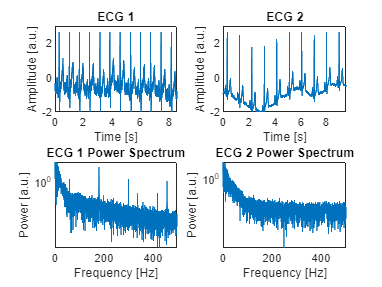

visualize_power(FS, ecg1, ecg2, P_ecg1, P_ecg2, f1, f2)

% Create moving average filter coefficients a and b:
b = (1/10)*ones(1,10)

b =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


a = 1

a = 1


% Do the filtering using a, b
ecg1_filtered = filter(b, a, ecg1)

ecg1_filtered =    -0.0714
   -0.1265
   -0.1724
   -0.2283
   -0.2856
   -0.3578
   -0.3985
   -0.4288
   -0.4622
   -0.5099


ecg2_filtered = filter(b, a, ecg2)

ecg2_filtered =    -0.0888
   -0.1801
   -0.2688
   -0.3568
   -0.4498
   -0.5405
   -0.6308
   -0.7225
   -0.8173
   -0.9148


% Frequency response
H = tf([1 -1], [1, -0.995])

H =
 
    s - 1
  ---------
  s - 0.995
 
Continuous-time transfer function.



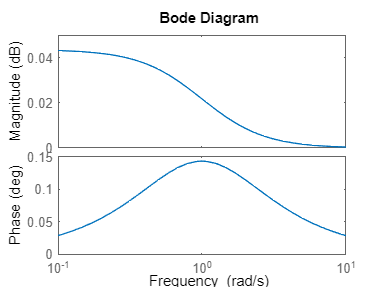

bode(H)

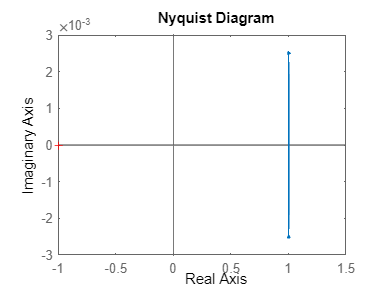

nyquist(H)

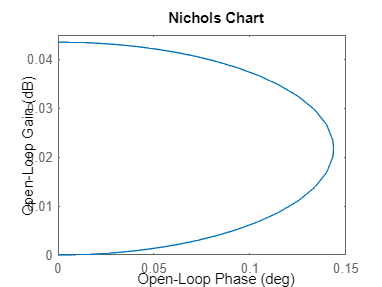

ans = 1.0025

nichols(H)

% Create derivative based filter coefficients a and b:
b = [1, -1]/real(max(freqz([1 -1], [1, -0.995])))

b =     0.9975   -0.9975


a = [1, -0.995]

a =     1.0000   -0.9950



% Do the filtering using a, b
ecg1_filtered = filter(b, a, ecg1)

ecg1_filtered =    -0.7126
   -0.5458
   -0.4514
   -0.5488
   -0.5601
   -0.7063
   -0.3886
   -0.2826
   -0.3128
   -0.4533


ecg2_filtered = filter(b, a, ecg2)

ecg2_filtered =    -0.8854
   -0.9071
   -0.8751
   -0.8646
   -0.9106
   -0.8820
   -0.8737
   -0.8842
   -0.9099
   -0.9328


% Create comb filter coefficients a and b:
b = [0.6310, -0.2149, 0.1512, -0.1288, 0.1227, -0.1288, 0.1512, -0.2149, 0.6310]
a = 1

% Do the filtering using a, b, and ecg1
ecg1_filtered = filter(b, a, ecg1)
ecg2_filtered = filter(b, a, ecg2)

% Create cascaded filter coefficients a and b using convolution
b = conv([0.6310, -0.2149, 0.1512, -0.1288, 0.1227, -0.1288, 0.1512, -0.2149, 0.6310], conv([1, -1]/real(max(freqz([1 -1], [1, -0.995]))), (1/10)*ones(1,10)))

b =     0.0629   -0.0214    0.0151   -0.0128    0.0122   -0.0128    0.0151   -0.0214    0.0629         0   -0.0629    0.0214   -0.0151    0.0128   -0.0122    0.0128   -0.0151    0.0214   -0.0629


a = conv(1, conv([1, -0.995], 1))

a =     1.0000   -0.9950



% Do the filtering using a, b
ecg1_filtered = filter(b, a, ecg1);
ecg2_filtered = filter(b, a, ecg2);

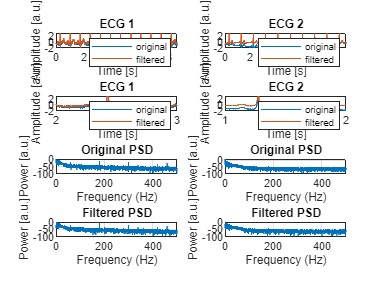

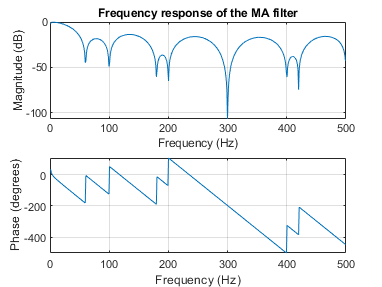

visualize_filter(FS, ecg1, ecg2, b, a, ecg1_filtered, ecg2_filtered)